Testul 8 - Balahura Vlad - grupa 231/1


$$f(x)=xsin(x2),[a,b]=[-\pi ,\pi ],m=9,t=5\pi $$


a) Sa se reprezinte pe acelasi grafic functia polinomul de interpolare Lagrange si polinomul de interpolare Hermite

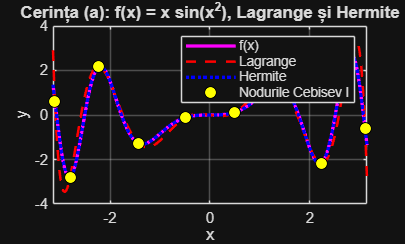

a = -pi; 
b = pi;
m = 9; 
t = pi/5;
n_total = m + 1;


f = @(x) x .* sin(x.^2);
df = @(x) sin(x.^2) + 2 * x.^2 .* cos(x.^2);

X_noduri = CebisevI(a, b, n_total);
Y_noduri = f(X_noduri);
dY_noduri = df(X_noduri);


xx_grafic = linspace(a, b, 500);
yy_exact = f(xx_grafic);

 
yy_Lagrange = LagrangeBary(X_noduri, Y_noduri, xx_grafic);


[yy_Hermite, ~] = Hermite_interpolare(X_noduri, Y_noduri, dY_noduri, xx_grafic);

figure('Name', 'Cerinta (a) - Interpolare Lagrange si Hermite');


plot(xx_grafic, yy_exact, 'm-', 'LineWidth', 2); hold on;
plot(xx_grafic, yy_Lagrange, 'r--', 'LineWidth', 1.5);
plot(xx_grafic, yy_Hermite, 'b:', 'LineWidth', 2);


plot(X_noduri, Y_noduri, 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);


title('Cerința (a): f(x) = x sin(x^2), Lagrange și Hermite');
xlabel('x'); 
ylabel('y');
legend('f(x)', 'Lagrange', 'Hermite', 'Nodurile Cebisev I');
grid on;
xlim([a b]);

b) Sa se aproximeze f(t) folosind toate tipurile de interpolare

val_exacta = f(t);

aprox_L = LagrangeBary(X_noduri, Y_noduri, t);

[aprox_H, ~] = Hermite_interpolare(X_noduri, Y_noduri, dY_noduri, t);

fprintf('Valoarea exactă f(t):       %15.10f\n', val_exacta);

Valoarea exactă f(t):          0.2416569461


fprintf('Aproximare Lagrange L(t):   %15.10f\n', aprox_L);

Aproximare Lagrange L(t):      0.3331872894


fprintf('Aproximare Hermite H(t):    %15.10f\n', aprox_H);

Aproximare Hermite H(t):       0.2410531230


c) 

Eroarea teoretica reprezinta marginea superioara a erorii pe care polinomul o poate avea în punctul t. Formulele folosite sunt:

$$$R_L(t) = \frac{f^{(10)}(\xi)}{10!} \prod_{k=0}^{9} (t - x_k)$$$ Unde $$f^{(10)}(\xi)$$ este derivata de ordin 10 a funcției $$x \sin x^2$$.

$$$R_H(t) = \frac{f^{(20)}(\eta)}{20!} \prod_{k=0}^{9} (t - x_k)^2$$$ Datorita dublarii nodurilor, restul Hermite implica derivata de ordin 20 si patratul produsului nodal, ceea ce conduce, teoretic, la o eroare mult mai mica decat in cazul Lagrange daca functia este suficient de neteda.

err_rel_practica_L = abs(val_exacta - aprox_L) / abs(val_exacta);
err_rel_practica_H = abs(val_exacta - aprox_H) / abs(val_exacta);


fprintf('Eroare relativa Lagrange: %e\n', err_rel_practica_L);

Eroare relativă practică Lagrange: 3.787615e-01


fprintf('Eroare relativa Hermite:  %e\n', err_rel_practica_H);

Eroare relativă practică Hermite:  2.498679e-03


Implementarea polinomului Lagrange folosind a doua forma baricentrica Am ales aceasta implementare pentru ca este mai stabila si mai rapida decat definitia clasica Lagrange, minimizand erorile de rotunjire

Pentru ca folosim noduri Cebisev de speta I, ponderile baridentrice se calculeaza astfel: 

    $$$w_j = (-1)^j \sin\left(\frac{2j+1}{2m}\pi\right)$$$ => $$$L(X) = \frac{\sum_{j=0}^{m-1} \frac{w_j f_j}{X - x_j}}{\sum_{j=0}^{m-1} \frac{w_j}{X - x_j}}$$$

function L = LagrangeBary(x, f, X)
    
    m = length(x);
    

    j = 0:m-1;
    w = ((-1).^j) .* sin((2*j + 1) * pi / (2 * m)); 
    
    L = zeros(size(X));
    for k = 1:length(X)
        x_pos_nod = find(x == X(k));
        
        if ~isempty(x_pos_nod)
            L(k) = f(x_pos_nod(1)); 
        else
            
            L(k) = sum(w .* f ./ (X(k) - x)) / sum(w ./ (X(k) - x));
        end
    end
end

Pentru implementarea Hermite, am folosit metoda diferentelor divizate generalizate si forma Newton a polinomului, pornind de la dublarea nodurilor $$z = [x_1, x_1, x_2, x_2, \dots, x_n, x_n]$$. Am construit tabelul $$T$$ prin completarea primei coloane cu valorile functiei $$T_{i,1} = f(z_i)$$, urmand ca pe coloana a doua sa inseram derivatele $$T_{2i,2} = f'(x_i)$$ si diferentele simple $$T_{2i-1,2} = \frac{f(x_i) - f(x_{i-1})}{x_i - x_{i-1}}$$. Restul tabelului pentru $$j \geq 3$$ a fost generat recursiv prin formula $$T_{i,j} = \frac{T_{i+1,j-1} - T_{i,j-1}}{z_{i+j-1} - z_i}$$, extragand apoi coeficientii $$c_k = T_{1,k}$$ de pe prima linie. Evaluarea finala in punctul $X$ s-a realizat prin formula $$H(X) = c_1 + \sum_{k=2}^{2n} c_k \prod_{j=1}^{k-1} (X - z_j)$$, calculand iterativ atat valoarea polinomului, cat si a derivatei sale

function [H, dH] = Hermite_interpolare(x, f, df, X)
    tabel_dif = dif_div_duble(x, f, df);
    
    c = tabel_dif(1, :);
    
   
    z = repelem(x, 2);

    H = zeros(size(X));
    dH = zeros(size(X));
    
    for k = 1:length(X)
        P = 1; 
        DP = 0; 
        H(k) = c(1); 
        dH(k) = 0;
        
        for i = 1:length(z)-1
            DP = DP * (X(k) - z(i)) + P;
            P = P * (X(k) - z(i));
            
            H(k) = H(k) + c(i+1) * P;
            dH(k) = dH(k) + c(i+1) * DP;
        end
    end
end

function T = dif_div_duble(x, f, df)
T = NaN(2 * length(x));
z = repelem(x, 2);

T(:, 1) = repelem(f, 2);
T(1:2:end, 2) = df;
T(2:2:end-2, 2) = diff(f) ./ diff(x);

for j = 3:length(z)
    for i = 1:length(z) + 1 - j
        T(i, j) = (T(i+1, j-1) - T(i, j-1)) / (z(i+j-1) - z(i));
    end
end
end

Calculam nodurile pe intervalul standard [-1,1] , dupa formula

    
$$$$t_k = \cos\left(\frac{2k+1}{2m}\pi\right), \quad k = 0, 1, \dots, m-1$$$$


Iar apoi aplicam o translatie in intervalul [a,b]


$$$$x_k = \frac{a+b}{2} + \frac{b-a}{2} t_k$$$$


function x = CebisevI(a, b, m)

j = 0:m-1;
x = cos((2*j + 1) * pi / (2 * m));
x = (a + b) / 2 + (b - a) / 2 * x;
end